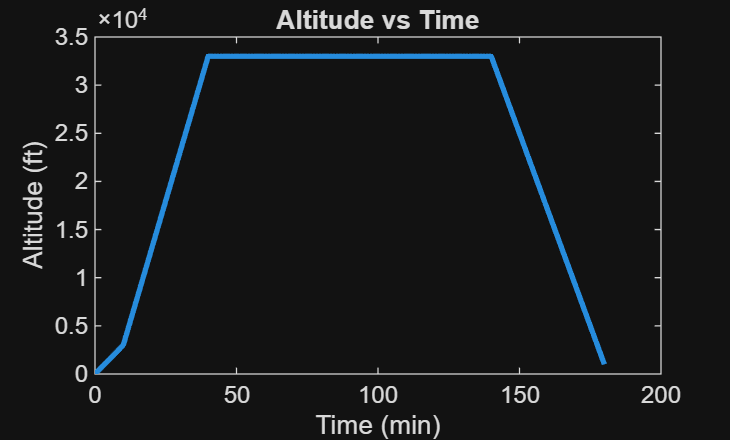

% Zulaikha Khan & Luis Lamas
% ES 115 Engineering Computer Applications
% Project 4: Aerospace Altitude & Speed Profile Analyzer
% Instructor: Lynroy Grant
% April 2026

clear; clc; close all;

% ----------------------------
% Time Data (minutes)
t = 0:1:180;

% ----------------------------
% Synthetic Altitude Data (feet)
alt = zeros(size(t));

% Takeoff (0–10 min)
alt(t <= 10) = 300 * t(t <= 10);

% Climb (10–40 min)
alt(t > 10 & t <= 40) = 3000 + 1000*(t(t > 10 & t <= 40) - 10);

% Cruise (40–140 min)
alt(t > 40 & t <= 140) = 33000;

% Descent (140–180 min)
alt(t > 140) = 33000 - 800*(t(t > 140) - 140);

% ----------------------------
% Speed Data (mph)
speed = zeros(size(t));

% Takeoff
speed(t <= 10) = 20*t(t <= 10);

% Climb
speed(t > 10 & t <= 40) = 200 + 5*(t(t > 10 & t <= 40) - 10);

% Cruise
speed(t > 40 & t <= 140) = 450;

% Descent
speed(t > 140) = 450 - 4*(t(t > 140) - 140);

% ----------------------------
% Phase Identification
phase = strings(size(t));

for i = 1:length(t)
    if alt(i) < 5000
        phase(i) = "Takeoff";
    elseif alt(i) >= 5000 && alt(i) < 30000
        phase(i) = "Climb";
    elseif alt(i) >= 30000 && speed(i) > 400
        phase(i) = "Cruise";
    else
        phase(i) = "Descent";
    end
end

% ----------------------------
% Plot 1: Altitude vs Time
figure;
plot(t, alt, 'LineWidth', 2);
xlabel('Time (min)');
ylabel('Altitude (ft)');
title('Altitude vs Time');

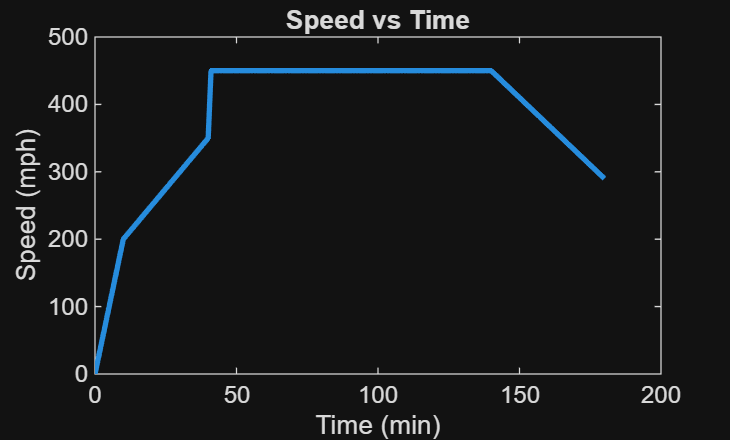


% ----------------------------
% Plot 2: Speed vs Time
figure;
plot(t, speed, 'LineWidth', 2);
xlabel('Time (min)');
ylabel('Speed (mph)');
title('Speed vs Time');

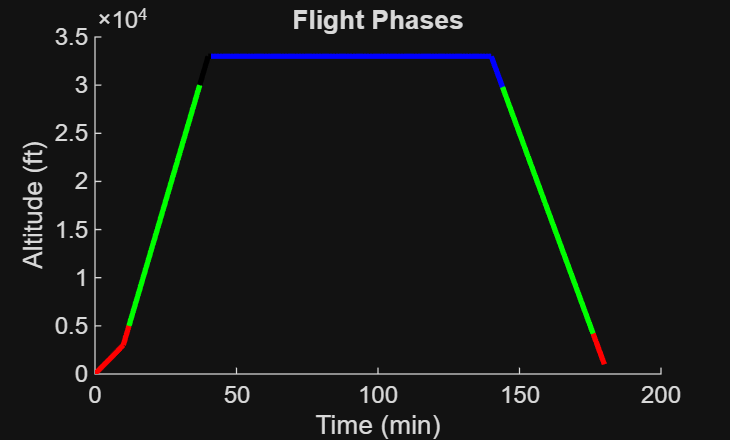


% ----------------------------
% Plot 3: Phase Colored Plot
figure;
hold on;
for i = 1:length(t)-1
    if phase(i) == "Takeoff"
        plot(t(i:i+1), alt(i:i+1), 'r', 'LineWidth', 2);
    elseif phase(i) == "Climb"
        plot(t(i:i+1), alt(i:i+1), 'g', 'LineWidth', 2);
    elseif phase(i) == "Cruise"
        plot(t(i:i+1), alt(i:i+1), 'b', 'LineWidth', 2);
    else
        plot(t(i:i+1), alt(i:i+1), 'k', 'LineWidth', 2);
    end
end
xlabel('Time (min)');
ylabel('Altitude (ft)');
title('Flight Phases');
hold off;

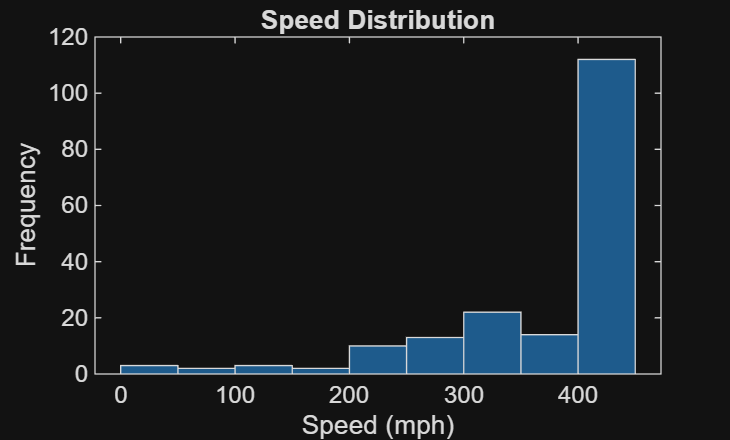


% ----------------------------
% Plot 4: Histogram of Speeds
figure;
histogram(speed);
xlabel('Speed (mph)');
ylabel('Frequency');
title('Speed Distribution');


% ----------------------------
% Metrics

% Climb rate (approx derivative)
climb_rate = diff(alt) ./ diff(t);
max_climb_rate = max(climb_rate);

% Average cruise speed
cruise_speeds = speed(phase == "Cruise");
avg_cruise_speed = mean(cruise_speeds);

% Descent duration
descent_time = t(phase == "Descent");
descent_duration = max(descent_time) - min(descent_time);

% Display Results
disp(['Max Climb Rate: ', num2str(max_climb_rate), ' ft/min']);

Max Climb Rate: 1000 ft/min


disp(['Average Cruise Speed: ', num2str(avg_cruise_speed), ' mph']);

Average Cruise Speed: 449.767 mph


disp(['Descent Duration: ', num2str(descent_duration), ' minutes']);

Descent Duration: 3 minutes
